## Load the data

% load the module data for 120 reps on R = 5, earlyStop = 60
% if it is of the full length, we need to set earlyStop = 100 with
% moduleResultfull.mat
clear; close all;
load('accuTypeMannual.mat');
load('allegiance.mat');
epochEarlystop = 100;
numInstance = 120;

parfor i = 1:numInstance
    i
    folderName_R_5_rep_120_diff_data{i} = sprintf('r_5_rep_120_diff_data/%d',i);
    dataFile_R_5_rep_120_diff_data{i} = load(sprintf('data/%s/moduleResultFull.mat',folderName_R_5_rep_120_diff_data{i}));
end


ans =

     1


ans =

     2


ans =

     3


ans =

     5


ans =

     8


ans =

    12


ans =

    18


ans =

    26


ans =

     4


ans =

     7


ans =

    11


ans =

    17


ans =

    25


ans =

    34


ans =

    42


ans =

    50


ans =

     6


ans =

    10


ans =

    16


ans =

    24


ans =

    33


ans =

    41


ans =

    49


ans =

    32


ans =

    40


ans =

    48


ans =

    58


ans =

     9


ans =

    15


ans =

    23


ans =

    57


ans =

    22


ans =

    14


ans =

    31


ans =

    39


ans =

    47


ans =

    56


ans =

    66


ans =

    21


ans =

    30


ans =

    38


ans =

    46


ans =

    65


ans =

    13


ans =

    29


ans =

    37


ans =

    45


ans =

    55


ans =

    64


ans =

    73


ans =

    20


ans =

    72


ans =

    54


ans =

    19


ans =

    28


ans =

    36


ans =

    44


ans =

    63


ans =

    71


ans =

    53


ans =

    27


ans =

    35


ans =



## Random test on the activation and correlation modularity

actVec = {};
corrVec = {};
selectedEpochIdx = 1:19:101;
kurtVals = zeros(epochEarlystop,numInstance);
skewVals = zeros(epochEarlystop,numInstance);
actMeanVals = zeros(epochEarlystop, numInstance);
actStdVals = zeros(epochEarlystop, numInstance);

%% plot the curve of representation kurtosis and skewness    
for j = 1:epochEarlystop
    j
    actVecSlice = [];
    corrVecSlice = [];
    for i = 1:numInstance
        tmpAct = dataFile_R_5_rep_120_diff_data{i}.a(:,:,j);
        tmpCorr = corr(tmpAct');
        actVecSlice = [actVecSlice, tmpAct(:)];
        upperIdx = tril(true(size(tmpCorr)),1);
        corrVecSlice = [corrVecSlice, tmpCorr(upperIdx)];
    end
    actMeanVals(j,:) = mean(actVecSlice);
    actStdVals(j,:) = std(actVecSlice);
    kurtVals(j,:) = kurtosis(actVecSlice);
    skewVals(j,:) = skewness(actVecSlice);
    corrMeanVals(j,:) = mean(corrVecSlice);
    corrStdVals(j,:) = std(corrVecSlice);
end

j = 1

j = 2

j = 3

j = 4

j = 5

j = 6

j = 7

j = 8

j = 9

j = 10

j = 11

j = 12

j = 13

j = 14

j = 15

j = 16

j = 17

j = 18

j = 19

j = 20

j = 21

j = 22

j = 23

j = 24

j = 25

j = 26

j = 27

j = 28

j = 29

j = 30

j = 31

j = 32

j = 33

j = 34

j = 35

j = 36

j = 37

j = 38

j = 39

j = 40

j = 41

j = 42

j = 43

j = 44

j = 45

j = 46

j = 47

j = 48

j = 49

j = 50

j = 51

j = 52

j = 53

j = 54

j = 55

j = 56

j = 57

j = 58

j = 59

j = 60

j = 61

j = 62

j = 63

j = 64

j = 65

j = 66

j = 67

j = 68

j = 69

j = 70

j = 71

j = 72

j = 73

j = 74

j = 75

j = 76

j = 77

j = 78

j = 79

j = 80

j = 81

j = 82

j = 83

j = 84

j = 85

j = 86

j = 87

j = 88

j = 89

j = 90

j = 91

j = 92

j = 93

j = 94

j = 95

j = 96

j = 97

j = 98

j = 99

j = 100

j = 101

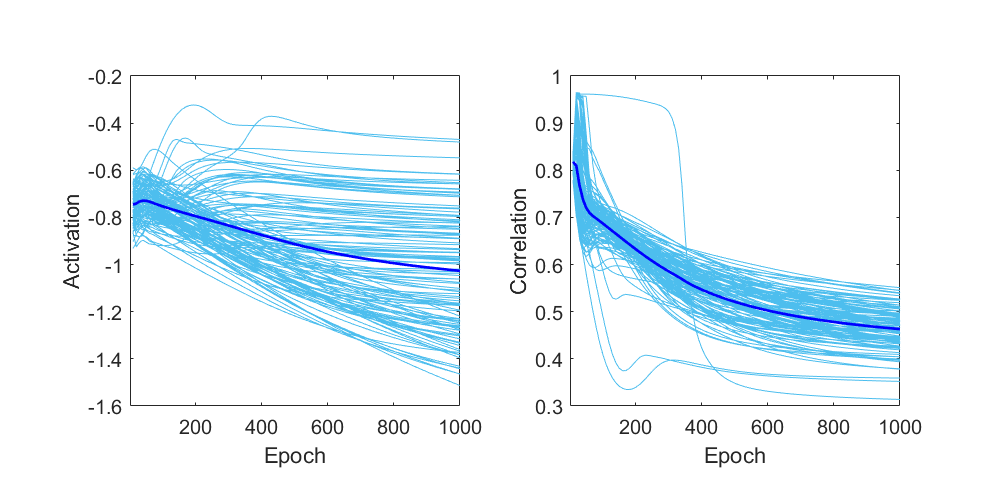

% plot the curve of mean activation and mean correlation
figure;
set(gcf,'position',[0,0,1000,500]); 
subplot(1,2,1);
for j = 1:numInstance
    ll = plot((1:epochEarlystop)*10, actMeanVals(:,j),'cyan'); 
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot((1:epochEarlystop)*10, mean(actMeanVals,2),'blue','LineWidth',2);
ylabel('Activation');
xlabel('Epoch'); xlim([1,1000]);
set(gca,'FontSize',15);
axis square;

subplot(1,2,2);
for j = 1:numInstance
    ll = plot((1:epochEarlystop)*10, corrMeanVals(:,j),'cyan'); 
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot((1:epochEarlystop)*10, mean(corrMeanVals,2),'blue','LineWidth',2);
ylabel('Correlation');
xlabel('Epoch');xlim([1,1000]);
set(gca,'FontSize',15);
axis square;

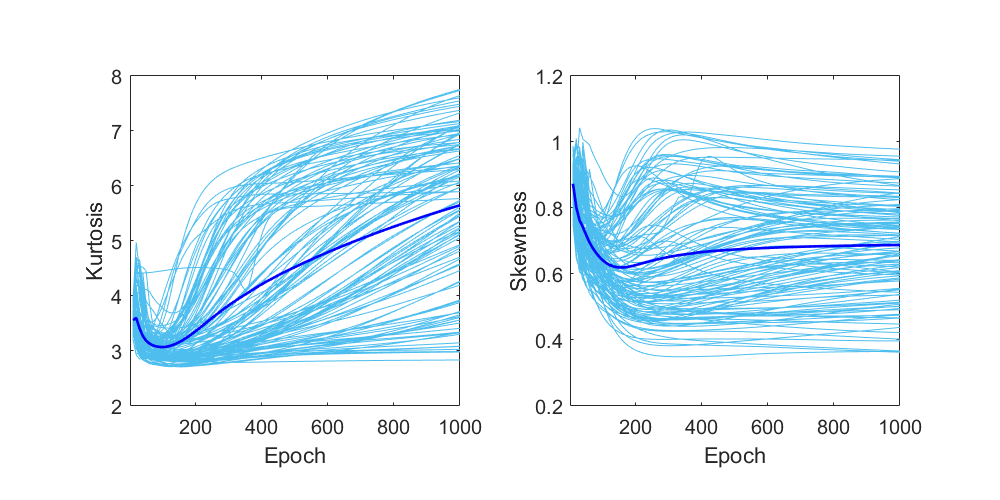

% plot the curve of kurtosis and skewness
figure;
set(gcf,'position',[0,0,1000,500]); 
subplot(1,2,1);
for j = 1:numInstance
    ll = plot((1:epochEarlystop)*10, kurtVals(:,j),'cyan'); 
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot((1:epochEarlystop)*10, mean(kurtVals,2),'blue','LineWidth',2);
ylabel('Kurtosis');
xlabel('Epoch'); xlim([1,1000]);
set(gca,'FontSize',15);
axis square;

subplot(1,2,2);
for j = 1:numInstance
    ll = plot((1:epochEarlystop)*10, skewVals(:,j),'cyan'); 
    ll.Color = [0.3010, 0.7450, 0.9330, 0.3];hold on;
end
plot((1:epochEarlystop)*10, mean(skewVals,2),'blue','LineWidth',2);
ylabel('Skewness');
xlabel('Epoch');xlim([1,1000]);
set(gca,'FontSize',15);
axis square;


for j = 1:numel(selectedEpochIdx)
    actVec{j} = [];
    corrVec{j} = [];
    for i = 1:numInstance
        tmp = dataFile_R_5_rep_120_diff_data{i}.a(:,:,selectedEpochIdx(j));
        actVec{j} = [actVec{j}; tmp(:)];
        corrVal = corr(tmp');
        upperIdx = tril(true(size(corrVal)),1);
        corrVec{j} = [corrVec{j}; corrVal(upperIdx)];
    end
end


for i = 1:120
    for j = 1:numel(selectedEpochIdx)
        allegianceMatrixSelected{i}(:,:,j) = squeeze(allegianceMatrix{i}(:,:,selectedEpochIdx(j)));
    end
end
rng(0);
iddx = randi(120)

iddx = 98

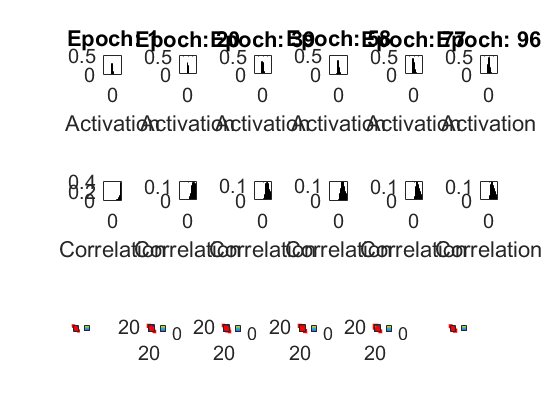


figure;
for i = 1:numel(selectedEpochIdx)
    subplot(3,numel(selectedEpochIdx),i);
    histogram(actVec{i},'NumBins', 20,'Normalization','probability');
    xlim([-40,40]); ylim([0,0.5]);
    xlabel('Activation');
    axis square;
    title(sprintf('Epoch: %d',selectedEpochIdx(i)));
    set(gca,'FontSize',15);

    
    subplot(3,numel(selectedEpochIdx),i+numel(selectedEpochIdx));
    histogram(corrVec{i},'NumBins',20,'Normalization','probability');
    xlim([-1,1]);
    xlabel('Correlation')
    axis square;
    set(gca,'FontSize',15);

    
    subplot(3,numel(selectedEpochIdx),i+2*numel(selectedEpochIdx));
    gplus = 1.00;
    Acell{1} = squeeze(allegianceMatrixSelected{iddx}(:,:,i));
    [cPartition{i}, allegiance{i}, modularityValue(i)] = genRobustCommunityFromASeries(Acell,gplus,1.0);
    colormap('parula');
    plotCommunities(Acell{1},cPartition{i},2); axis square; colorbar;
    set(gca,'FontSize',15);
end

% add mediaton analysis for the increase of accuracy?

























